# FMCW Radar Lab: Constant False Alarm Rate (CFAR)

This script demonstrates how a Constant False Alarm Rate (CFAR) algorithm can be used to process target return data and output the range and velocity of suspected targets. In this lab, we use a 2-dimensional CFAR algorithm on the processed range-Doppler data with an MTI filter applied to search for target detections.

## System Setup

Before going through the lab, we prepare the workspace by clearing variables, closing figures, suppressing warnings.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

For this lab, we use many of the same parameters that were used in previous labs.

fc = 10e9;
prf = 1000;
nPulses = 50;
fs = 1e6;
rampbandwidth = 500e6;
[rx,tx,bf,bf_TDD] = setupLabRadar(fc,prf,nPulses,fs,rampbandwidth);
mti = [1 -2 1];
nfilt = length(mti);

## CFAR Setup

The key parameter in the CFAR algorithm is the probability of false alarm, which remains constant (hence the name). CFAR assumes gaussian noise, and looks for outliers in the collected data. The number of standard deviations that the outliers must be to be considered a detection is based on this probability of false alarm. If the probability of false alarm is set to a higher value, we will see more false alarms but also reduce the liklihood that we miss a true target detection. If the probability of false alarm is set to a lower value, we will see fewer false alarms, but also increase the liklihood that we miss a true target detection.

pfa = 1e-7;

Setup the CFAR detector. We can adjust the guard and training cell based on our observation of detection performance.

guard = 2;
train = 2;
cfar = phased.CFARDetector2D(ProbabilityFalseAlarm=pfa,GuardBandSize=[guard guard],TrainingBandSize=[train train])

cfar =   phased.CFARDetector2D with properties:

                   Method: 'CA'
            GuardBandSize: [2 2]
         TrainingBandSize: [2 2]
          ThresholdFactor: 'Auto'
    ProbabilityFalseAlarm: 1.0000e-07
             OutputFormat: 'CUT result'
      ThresholdOutputPort: false
     NoisePowerOutputPort: false


It is desireable to perform CFAR on only the cells that you are interested in. Therefore, we avoid performing CFAR on cells near 0 Doppler as the response in these cells is being filtered out by the MTI filter. Also, CFAR cannot be performed on cells too close to the border of the range-Doppler image if there are not enough guard and training cells. Therefore, we specify the min and max ranges at which we would like to test cells for the presence of a detection. Also, we ensure that we are not testing cells too close to the border image.

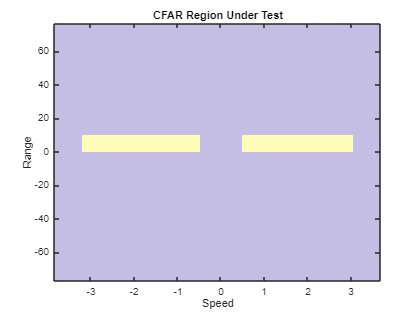

% Specify the min and max ranges to include in CFAR
minRange = 0;
maxRange = 10;

% Specify the min and max velocity to include in CFAR
vmin = 0.5;
vmax = inf;

% Get the CFAR cells under test (CUT) and plot
tSweep = double(bf.FrequencyDeviationTime)/1e6;
[cut,speed,range] = getCFARCUT(minRange,maxRange,vmin,vmax,guard,train,prf,nPulses-nfilt,fc,fs,tSweep,rampbandwidth);
plotCFARRegion(cut,range,speed);

The yellow regions are the regions of the range-Doppler space that we will be testing for detections.

## Data Collection

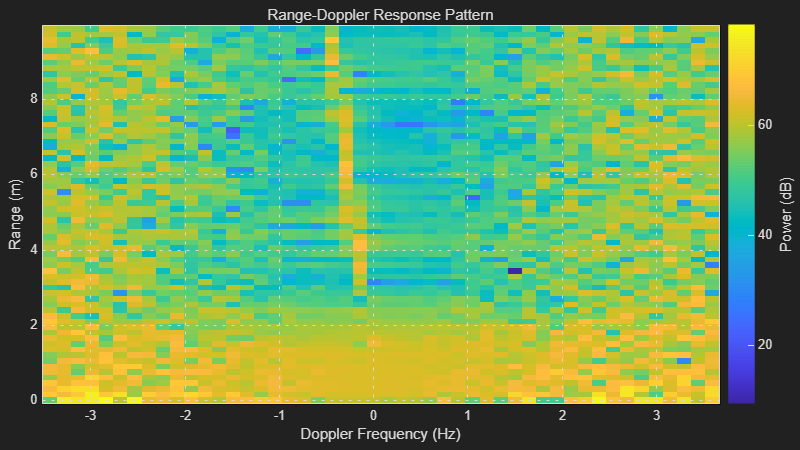

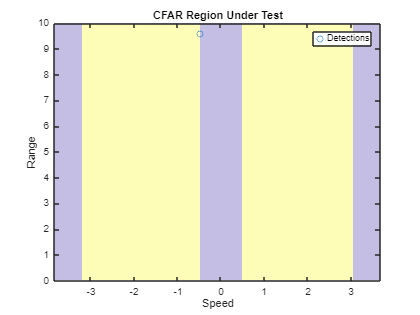

% Run time in seconds
tCapture = 30;

% Create a range-Doppler response for processing
sweepSlope = rampbandwidth/tSweep;
rd = phased.RangeDopplerResponse(DopplerOutput="Speed",...
    OperatingFrequency=fc,SampleRate=fs,RangeMethod="FFT",...
    SweepSlope=sweepSlope,PRFSource="Property",PRF=prf);
scope = phased.RangeDopplerScope(IQDataInput=false);

% Create axes to plot detections
ax = plotCFARRegion(cut,range,speed);
hold(ax,"on");
points = scatter(ax,0,0,DisplayName='Detections');
legend(points);
ylim(ax,[minRange maxRange]);

% Capture the first waveform which typically has 0 values
captureTransmitWaveform(rx,tx,bf);

t = tic;
while toc(t) < tCapture
    % capture data
    data = captureTransmitWaveform(rx,tx,bf);

    % Arrange data into pulses for processing
    data = arrangePulseData(data,rx,bf,bf_TDD);

    % Apply MTI filter, remove pulses in transient region
    data = filter(mti,1,data,[],2);
    data = data(:,nfilt:end);

    % Calculate the range-Doppler response
    [resp,range,speed] = rd(data);
    scope(abs(resp(range >= minRange & range <= maxRange,:)),range(range >= minRange & range <= maxRange),speed);

    % Get detections
    d = cfar(abs(resp).^2,cut);

    % Plot the detections
    detidx = cut(:,d');
    set(points,'XData',speed(detidx(2,:)),'YData',range(detidx(1,:)));

    drawnow;
end


% Disable TDD Trigger
cleanupAntenna(rx,tx,bf,bf_TDD);


function ax = plotCFARRegion(cut,range,speed)
    % Plot the CFAR region that will be tested for detections
    
    % Create axes to plot region
    ax = axes(figure);
    
    % Plot the cfar region image
    cfartest = zeros(length(range),length(speed));
    ncut = size(cut,2);
    for iCut = 1:ncut
        cfartest(cut(1,iCut),cut(2,iCut)) = 1;
    end
    imagesc(ax,speed,range,cfartest,'AlphaData',0.3);
    
    % Update axes
    title(ax,'CFAR Region Under Test');
    xlabel(ax,'Speed');
    ylabel(ax,'Range');
    ax.YDir = "Normal";
end

function [cut,speed,range] = getCFARCUT(minRange,maxRange,vmin,vmax,guard,train,prf,nPulses,fc,fs,tSweep,rampbandwidth)
    % Exclude cells to close to the border
    nexclude = guard+train;

    % Get speed region for testing
    df = prf/nPulses;
    fdop = -prf/2:df:prf/2-df;
    speed = dop2speed(fdop,freq2wavelen(fc))/2;
    keepSpeed = abs(speed) >= vmin & abs(speed) <= vmax;
    keepSpeed(1:nexclude) = false;
    keepSpeed(end-nexclude+1:end) = false;
    speedidxs = find(keepSpeed);

    % Get range region for testing - assume that we will not run into the
    % border at higher ranges
    nSamples = ceil(tSweep * fs);
    dr = physconst('LightSpeed')*(fs/nSamples)*tSweep/(rampbandwidth*2);
    maxAvailRange = nSamples*dr;
    range = -maxAvailRange/2:dr:maxAvailRange/2-dr;
    keepRange = range >= minRange & range <= maxRange;
    keepRange(1:nexclude) = false;
    keepRange(end-nexclude+1:end) = false;
    rangeidxs = find(keepRange);

    % Generate cells under test
    nspeed = length(speedidxs);
    nrange = length(rangeidxs);
    cut = zeros(2,nspeed*nrange);
    cidx = 1;
    for iRange = 1:nrange
        for iSpeed = 1:nspeed
            cut(1,cidx) = rangeidxs(iRange);
            cut(2,cidx) = speedidxs(iSpeed);
            cidx = cidx + 1;
        end
    end
end